n_grid = 20;  % Size of grid
Ms = [];
Ts = [];
Ns = [];
Es = [];




## Monte Carlo Loopn

Error using matlab.graphics.axis.Axes/get
Operation terminated by user

Error in xlabel (line 39)
    h = get(ax,'XLabel');

Error in ising (line 28)
    xlabel(sprintf('T = %0.2f, M = %0.2f, E = %0.2f', T, M/N^2, E/N^2));


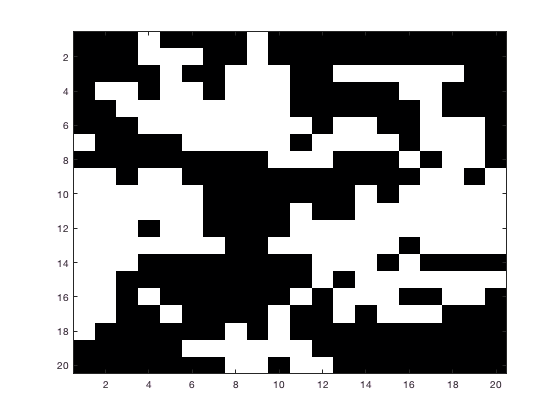

for n_iter= 1:2000
%while (n_iter<3000),
    % Choose a temperature
    T = rand()*5+1e-10;
    % Perform a simulation
    [M, N, E] = ising(n_grid, T);
    % Record the results
    Ms = [Ms M/(n_grid^2)];
    Es = [Es E/(n_grid^2)];
    Ns = [Ns N];
    Ts = [Ts T];
    n_ter=n_iter+1;
end

## Figure Generation

Energy per site, versus temperature

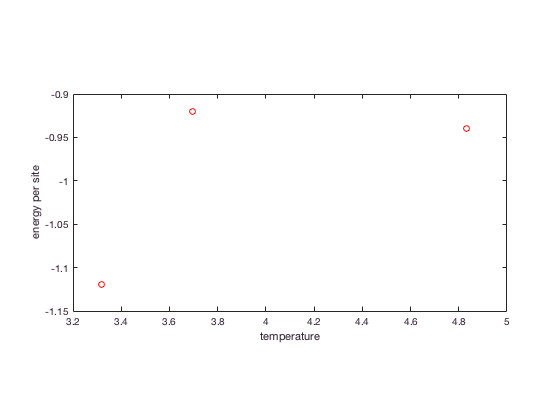

plot(Ts, Es, 'ro');
ylabel('energy per site');
xlabel('temperature');
pbaspect([2 1 1]);
print(gcf, '-depsc2', 'ising-energy');

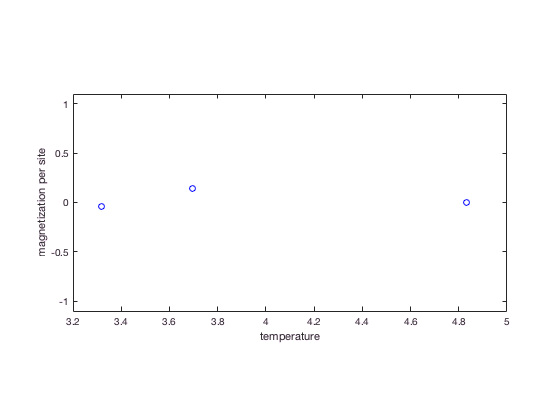

% Magnetization per site, versus temperature
plot(Ts, Ms, 'bo');
ylabel('magnetization per site');
xlabel('temperature');
ylim([-1.1 1.1]);
pbaspect([2 1 1]);
print(gcf, '-depsc2', 'ising-magnetization');

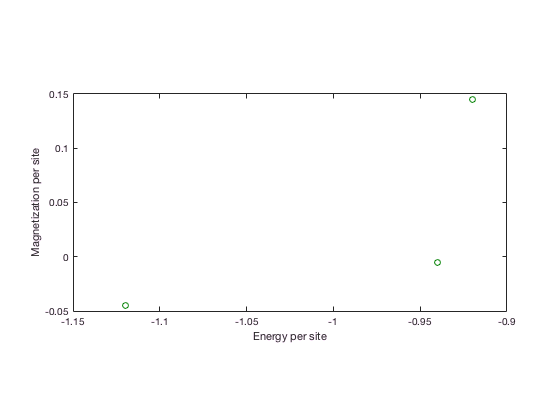

% Magnetization per site, versus Energy per site
plot(Es, Ms, 'o', 'Color', [0 0.5 0]);
xlabel('Energy per site');
ylabel('Magnetization per site');
pbaspect([2 1 1]);
print(gcf, '-depsc2', 'ising-mvse');